**REGULATEUR PID**

**1: Observation de l'influence des coefficients du PID**

Pour analyser le comportement d'un régulateur PID, nous allons faire varier les coefficients de proportionalité (kp), d'intégartion (ki) et de dérivation (kd) en utilisant P(s)= 1/(1+s)^3 et C(s)=(Kp*s + Ki + Kd * s^2) / s et L(s)=P(s) * C(s)

s = tf('s');
P = 1/(s+1)^3;


- ***Coefficient de proportionnalité (kp):***

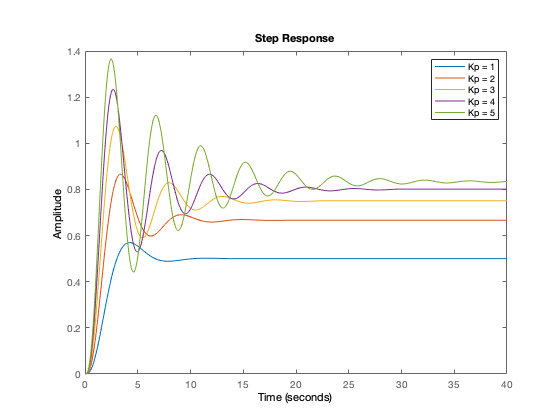

clc, close all, clear all;
s = tf('s');
P = 1/(s+1)^3;
figure(1); hold on;
figure(2); hold on;
figure(3); hold on;
labels = {};

for i = 1:5
    Kp = i;
    Ki = 0;
    Kd = 0;

    labels{end+1} = ['Kp = ' num2str(Kp)];

    C = (Kp*s+Ki+Kd*s^2)/s;

    L = P*C;

    figure(1);
    step(L/(1+L));
    figure(2);
    margin(L);
    figure(3);
    nyquist(L);
end
figure(1); legend(labels);

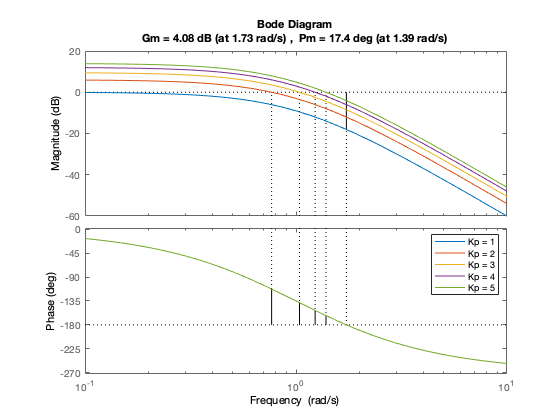

figure(2); legend(labels);

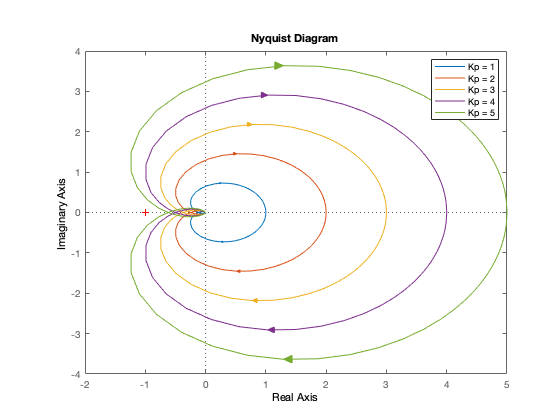

figure(3); legend(labels);

Nous pouvons observer que plus le coefficient k(p) est élevé, plus la vitesse de montée vers la valeur souhaitée est rapide. Augmenter la valeur de k(p) revient donc à augmenter la réactivité du système.

Par contre plus le coefficient est élevé, plus des oscillations apparaissent ce qui signifie que la stabilité diminue.

Le Diagramme de Bode qui permet la représentation fréquentielle, montre que l'augmentation de K(p) diminue la marge de phase.

On choisira Kp pour avoir le meilleur compromis entre rapidité, précision et stabilité. 

- ***Coefficient de d'integration (ki):***

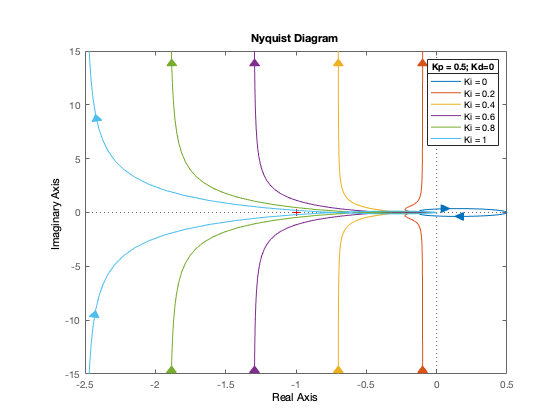

s = tf('s');
P = 1/(s+1)^3;

figure(4); hold on;
figure(5); hold on;
figure(6); hold on;
labels = {};

for i = 0:5
    Kp = 0.5;
    Ki = i*0.2;
    Kd = 0;

    labels{end+1} = ['Ki = ' num2str(Ki)];

    C = (Kp*s+Ki+Kd*s^2)/s;

    L = P*C;

    figure(4);
    step(L/(1+L));
    figure(5);
    margin(L);
    figure(6);
    nyquist(L);
end
lgd = legend(labels);
figure(4); title(lgd, 'Kp = 0.5; Kd=0');

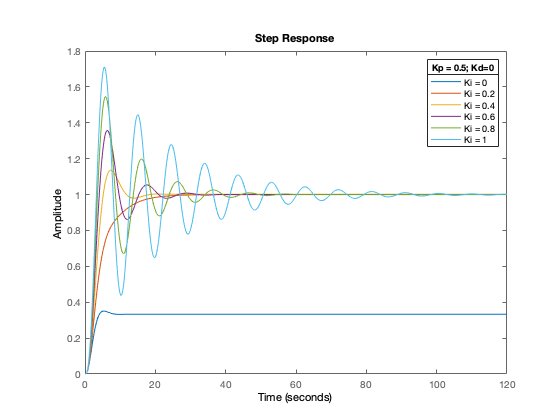

lgd = legend(labels);
figure(5); title(lgd, 'Kp = 0.5; Kd=0');

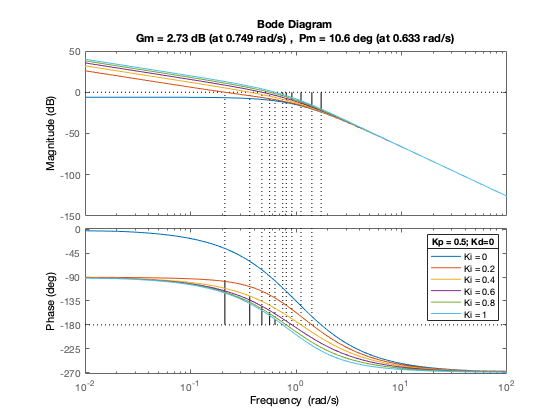

lgd = legend(labels);
figure(6); title(lgd, 'Kp = 0.5; Kd=0');

On constate lorsqu’on augmente la valeur de Ki, que l'on augmente la précision du système mais le système est moins stable.

Le coefficient d'intégration permet de tendre vers la valeur attendue de notre système en réduisant les erreurs. En réalisant cette opération, nous pouvons observer sur le diagramme de Bode que notre gain sera supérieur en basse fréquence.

On choisira Ki pour avoir le meilleur compromis entre précision et stabilité.

- ***Coefficient de d'integration (kd):***

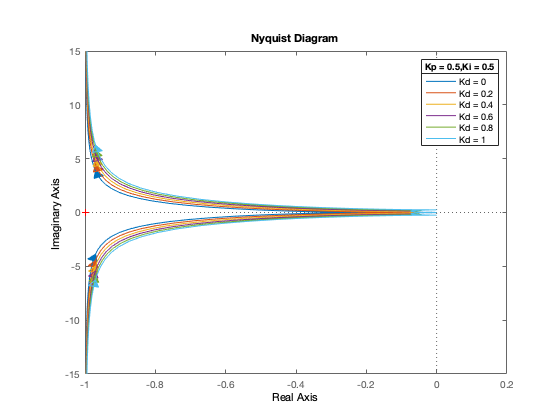

s = tf('s');
P = 1/(s+1)^3;

figure(7); hold on;
figure(8); hold on;
figure(9); hold on;
labels = {};

for i = 0:5
    Kp = 0.5;
    Ki = 0.5;
    Kd = i*0.2;

    labels{end+1} = ['Kd = ' num2str(Kd)];

    C = (Kp*s+Ki+Kd*s^2)/s;

    L = P*C;
    figure(7);
    step(L/(1+L));
    figure(8);
    margin(L);
    figure(9);
    nyquist(L);
end
lgd = legend(labels);
figure(7); title(lgd, 'Kp = 0.5,Ki = 0.5');

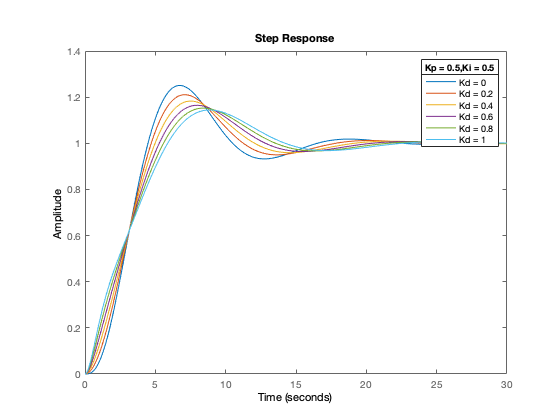

lgd = legend(labels);
figure(8); title(lgd, 'Kp = 0.5,Ki = 0.5');

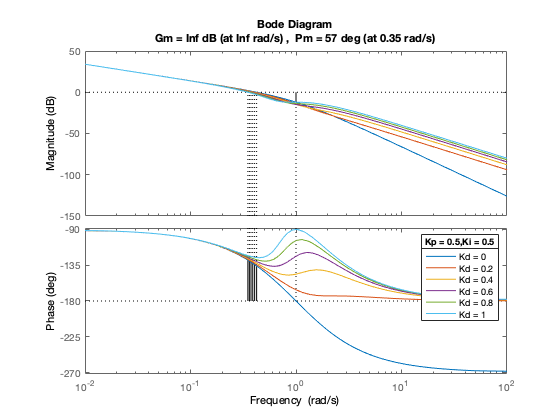

lgd = legend(labels);
figure(9); title(lgd, 'Kp = 0.5,Ki = 0.5');

Notre dernière variable de régulation, le coefficient de dérivation Kd permet de réduire les ondulations. En effet, celui-ci va faire tendre la valeur la courbe vers une tendance futur. En introduisant ce terme, nous obtenons donc une meilleure stabilité. Ceci est visible sur le diagramme de Nyquist avec une augmentation de la marge de phase et de gain. Toutefois, il est important de préciser que notre marge de gain tend vers l'infini sur la simulation et ceci est strictement impossible sur des systèmes réels. Il est donc nécéssaire d'obter pour un système d'anti wind-up.

- ***Boucle ouverte / fermée:***

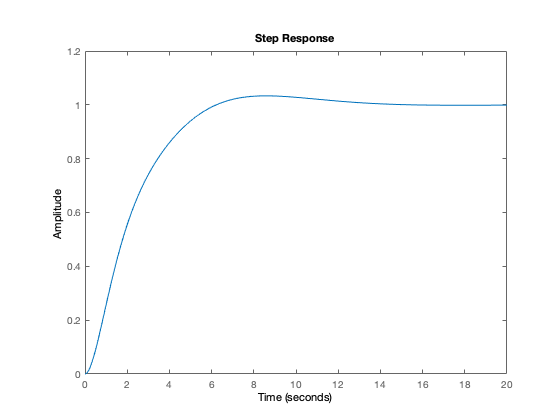

s = tf('s');

P = 1/(s+1)^3;

Kp = 1;
Ki = 0.5;
Kd = 1;

C = (Kp*s+Ki+Kd*s^2)/s;

L = P*C;

figure(10); step(L/(1+L));

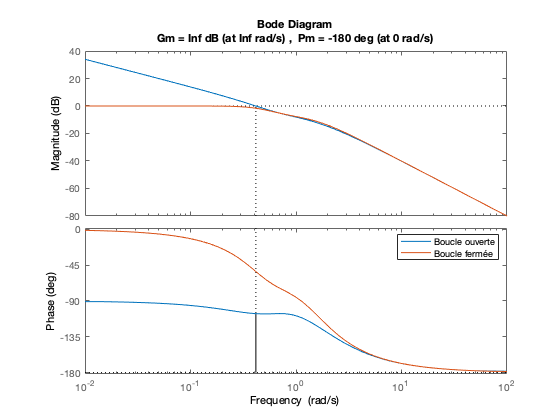


figure(11); hold on; margin(L); margin(L/(1+L)); legend('Boucle ouverte', 'Boucle fermée');

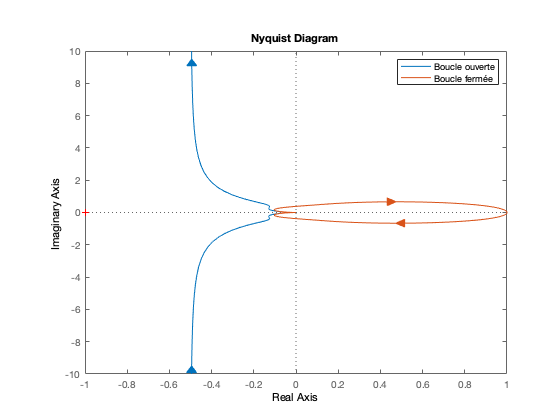

figure(12); hold on; nyquist(L); nyquist(L/(1+L)); legend('Boucle ouverte', 'Boucle fermée');

Le diagramme de Nyquist nous donne une représentation de la stabilité de notre système. Le système est stable en boucle fermée si le point critique (-1,0) est laissé à la gauche de la courbe tracée pour une pulsation variant de 0 à l'infini. Ce diagramme nous permet également de déterminer facilement les différentes marges de stabilité.

Sur le diagramme de Bode, la marge de gain est positive si la courbe de gain est en-dessous de l'axe 0 dB pour la pulsation critique qui correspond à l'intersection de la courbe de phase avec l'axe -180°. La marge de phase est positive si la courbe de phase est au-dessus de l'axe -180° pour la pulsation correspondant à l'intersection de la courbe de gain avec l'axe 0 dB.

En comparant les réponses fréquentielles de la boucle ouverte et de la boucle fermée, on observe bien que le système bouclé correspond au minimum entre notre observation (ici 1) et notre entrée. De ce fait, à basse fréquence on a un gain de 0dB (correspondant à 1) puis à haute fréquence le gain de la fonction de transfert 𝐿. Entre les deux on a un compromis dans les valeurs. 

**2: Régulateur de vitesse:**

**2.1 - Modèle Linéaire.**

Notre objectif est de liénairiser notre système en suivant ce modèle :

Nous souhaitons régulariser uniquement le paramètre de la vitesse, nous pouvons donc simplifier notre équation de sortie avec **C = 1 **et** D = 0**: 

A présent, nous cherchons de passer du modèle de l'équation différentielle à l'équation d'état : 

- a=(an^2*u_e*pT-rho*Cd*A*v_e)/m;

- b=an*T/m; 

- bg=g*cos(theta_e);

avec donc : 

A = a;

B = b - bg;

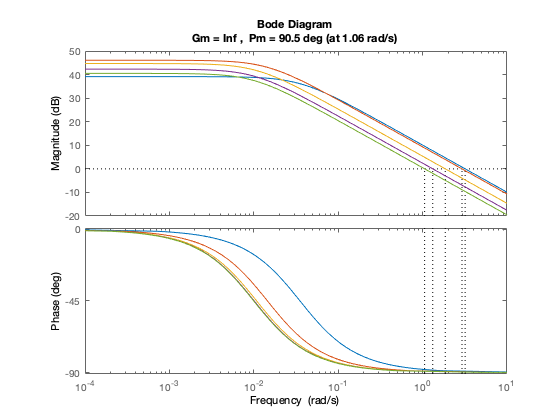

clear all;
close all;

figure(20); hold on;
figure(21); hold on;

labels = {};
for gear = 1:5
    cruise_carpar
    %Compute the trottle u_e required to keep velocity ve
    %at slope thetae, velocity ve, and gear
    an=gears(gear);
    A0=Tm*an*(1-bbeta*(an*v_e/wm-1)^2);
    A1=m*g*Cr+rho*Cd*A*v_e^2/2+m*g*sin(theta_e);
    u_e=A1/A0;

    %Compute linearized model
    w=an*v_e;
    T=Tm*(1-bbeta*(w/wm-1)^2);
    pT=-2*bbeta*Tm*(w/wm-1)/wm;
    a=(an^2*u_e*pT-rho*Cd*A*v_e)/m;
    b=an*T/m;
    bg=g*cos(theta_e);
    labels{end+1} = ['Gear = ' num2str(gear)];
    
    
    A = a;
    B = b;
    C = 1;
    D = 0;
    systemeb = ss(A, B, C, D);
    figure(20);
    margin(systemeb);
        A = a;
    B = - bg;
    C = 1;
    D = 0;
    systemebg = ss(A, B, C, D);
    
    figure(21);
    margin(systemebg);
end 

lgd = legend(labels);
figure(20); title(lgd, 'Réponse Fréquentielle avec B = b ');hold off;

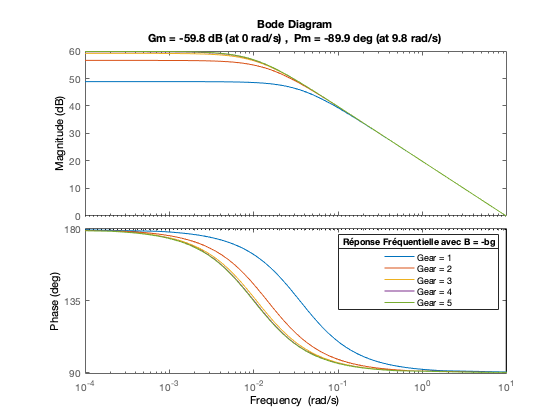

figure(21); title(lgd, 'Réponse Fréquentielle avec B = -bg ');hold off;

**2.2 - Boucle de régulation**

Mise en place du système anti-windup:

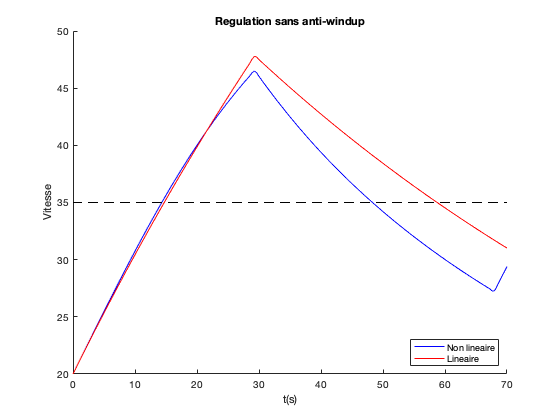

clc, close all, clear all;
%% PI control with antiwindup for linear and nonlinear models
%% Controller set

kp = 1;
ki = 1;
kt = 1;

theta_d = 0;		% set the hill angle
gear    = 4;             % gear

v_ref = 35;
param = [kp, ki, kt, theta_d, gear, v_ref];

%% Car parameters
cruise_lin
% Defines operating conditions

%% PI controller simulation of linear and nonlinear models
%

% TO COMPLETE 
% USE ODE45 FUNCTION FOR CRUISE_CLSYSODE.M 
% BETWEEN 0-70 WITH INITIAL CONDITIONS [v_e u_e]
[t, x]  = ode45(@(t,x) cruise_clsysode(t, x, param, 0), [0 70], [v_e v_e u_e u_e]);
t_ss_w  = t;
x_ss_w  = x;

clearvars x;

[t, x]  = ode45(@(t,x) cruise_clsysode(t, x, param, 1), [0 70], [v_e v_e u_e u_e]);
t_av_w  = t;
x_av_w  = x;

% Sans windup
e_nl_ss_w    = v_ref - x_ss_w(:,1);
uu_nl_ss_w   = kp*e_nl_ss_w + ki*(x_ss_w(:,3));
u_nl_ss_w    = min(max(0, uu_nl_ss_w), 1);

e_l_ss_w     = v_ref - x_ss_w(:,2);
uu_l_ss_w    = kp*e_l_ss_w + ki*(x_ss_w(:,4));
u_l_ss_w     = min(max(0, uu_l_ss_w), 1);

% Avec windup
e_nl_av_w   = v_ref - x_av_w(:,1);
uu_nl_av_w  = kp*e_nl_av_w + ki*(x_av_w(:,3));
u_nl_av_w   = min(max(0, uu_nl_av_w), 1);

e_l_av_w   = v_ref - x_av_w(:,2);
uu_l_av_w  = kp*e_l_av_w + ki*(x_av_w(:,4));
u_l_av_w   = min(max(0, uu_l_av_w), 1);

%% Plot the results
% Compute control signal for plotting
figure(13);
hold on; plot(t_ss_w, x_ss_w(:,1), 'b'); plot(t_ss_w, x_ss_w(:, 2), 'r'); plot(t_ss_w, v_ref*ones(length(t_ss_w)), 'black--');
legend('Non lineaire', 'Lineaire', 'Location', 'southeast');
xlabel('t(s)'); ylabel('Vitesse'); title('Regulation sans anti-windup');

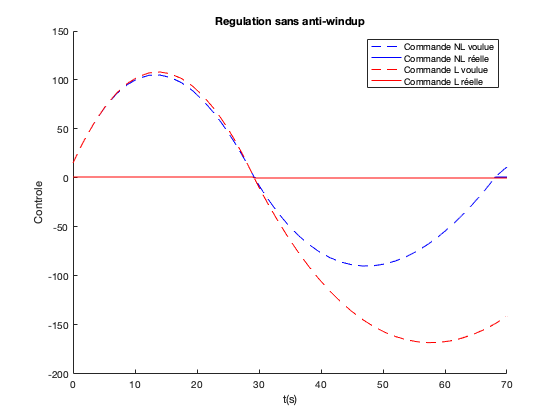


figure(14);
hold on; plot(t_ss_w, uu_nl_ss_w, 'b--'); plot(t_ss_w, u_nl_ss_w, 'b'); plot(t_ss_w, uu_l_ss_w, 'r--'); plot(t_ss_w, u_l_ss_w, 'r');
legend('Commande NL voulue', 'Commande NL réelle', 'Commande L voulue', 'Commande L réelle');
xlabel('t(s)'); ylabel('Controle');title('Regulation sans anti-windup');

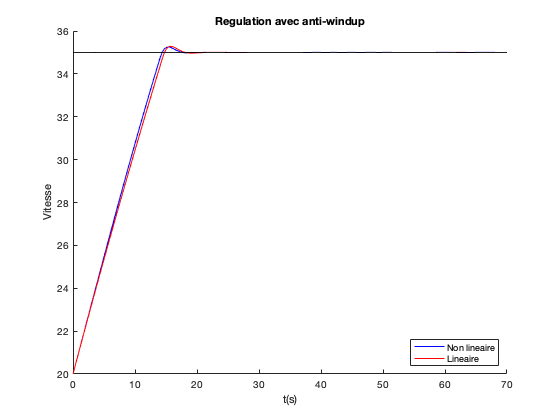


figure(15);
hold on; plot(t_av_w, x_av_w(:,1), 'b'); plot(t_av_w, x_av_w(:, 2), 'r'); plot(t_av_w, v_ref*ones(length(t_av_w)), 'black--');
legend('Non lineaire', 'Lineaire', 'Location', 'southeast');
xlabel('t(s)'); ylabel('Vitesse'); title('Regulation avec anti-windup');

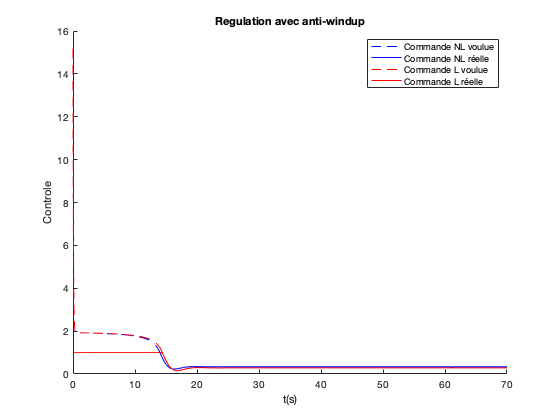


figure(16);
hold on; plot(t_av_w, uu_nl_av_w, 'b--'); plot(t_av_w, u_nl_av_w, 'b'); plot(t_av_w, uu_l_av_w, 'r--'); plot(t_av_w, u_l_av_w, 'r');
legend('Commande NL voulue', 'Commande NL réelle', 'Commande L voulue', 'Commande L réelle');
xlabel('t(s)'); ylabel('Controle');title('Regulation avec anti-windup');

s = tf('s');% speed error
P = ss(a, [bg b], 1, 0);% throttle
C = (kp*s+ki)/s;% saturate throttle 
L = P*C;% throttle for linear model 



- **Intéret du système anti-windup:**

Les courbes ci-dessus montre bien l'intéret du système anti-windup. Le système va permètre de limiter les dépassements de vitesse autour du point de consigne en éliminant les dépassements sur la commande.

Sans le système, les passagers de la voiture subiraient des accoups désagréables le temps que la vitesse se stabilse entre chaque changement de régimes.

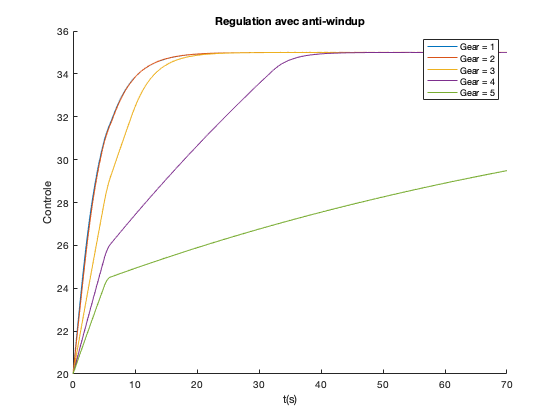

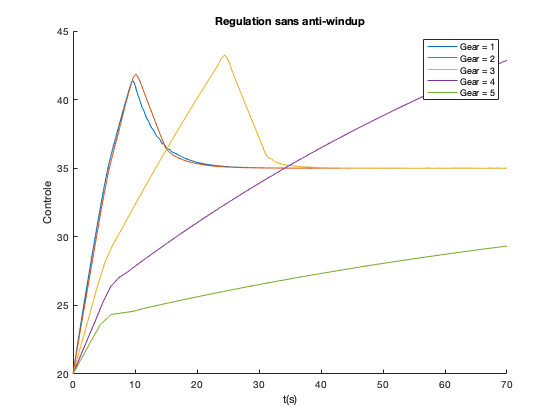

clc, close all, clear all;
%% PI control with antiwindup for linear and nonlinear models
%% Controller set

kp = 1;
ki = 0.5;
kt = 2;

theta_d = 4;		% set the hill angle
gear    = 4;             % gear
labels = {};
figure(17);hold on;
figure(18);hold on;
for gear=1:5
 
    labels{end+1} = ['Gear = ' num2str(gear)];
    v_ref = 35;
    param = [kp, ki, kt, theta_d, gear, v_ref];
    
    %% Car parameters
    cruise_lin
    % Defines operating conditions
    
    %% PI controller simulation of linear and nonlinear models
    %
    
    % TO COMPLETE 
    % USE ODE45 FUNCTION FOR CRUISE_CLSYSODE.M 
    % BETWEEN 0-70 WITH INITIAL CONDITIONS [v_e u_e]
    [t, x]  = ode45(@(t,x) cruise_clsysode(t, x, param, 0), [0 70], [v_e v_e u_e u_e]);
    t_ss_w  = t;
    x_ss_w  = x;
    
    clearvars x;
    
    [t, x]  = ode45(@(t,x) cruise_clsysode(t, x, param, 1), [0 70], [v_e v_e u_e u_e]);
    t_av_w  = t;
    x_av_w  = x;
    
    % Sans windup
   
    e_l_ss_w     = v_ref - x_ss_w(:,2);
    uu_l_ss_w    = kp*e_l_ss_w + ki*(x_ss_w(:,4));
    u_l_ss_w     = min(max(0, uu_l_ss_w), 1);
    
    % Avec windup
   
    e_l_av_w   = v_ref - x_av_w(:,2);
    uu_l_av_w  = kp*e_l_av_w + ki*(x_av_w(:,4));
    u_l_av_w   = min(max(0, uu_l_av_w), 1);
    
    %% Plot the results
    % Compute control signal for plotting
    figure(17);
    plot(t_av_w, x_av_w(:, 2));
    legend(labels)
    xlabel('t(s)'); ylabel('Controle');title('Regulation avec anti-windup');
    
    figure(18);
    plot(t_ss_w, x_ss_w(:, 2));
    legend(labels)
    xlabel('t(s)'); ylabel('Controle');title('Regulation sans anti-windup');
    end

- Pour le modèle dynamique avec anti-wind-up et kp=1 et ki=0.5 et kt=2 ,  nous obtenons des dépassements très faibles même en modifiant la masse et la pente pour une vitesse '3' et un vref à 35Km/h:

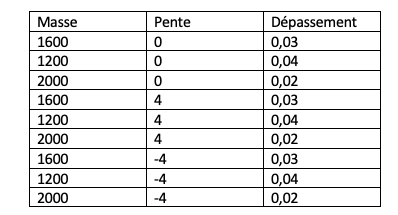

Pour un réglage en vitesse 4 ou 5, la voiture manque de couple, et la vitesse n'est donc pas atteinte dans les 70s

- **Intéret de l'intégrateur:**

Avec un Ki réglé à 0, nous n'atteignons jamais la vitesse de consigne, nous avons une erreur statique, il est donc important de l'intégré à la régulation du véhicule.

**2.3 - Vérifier le lien entre les performances temporelles et la réponse fréquentielle en boucle ouverte.**

boucle ouverte: L = P*C

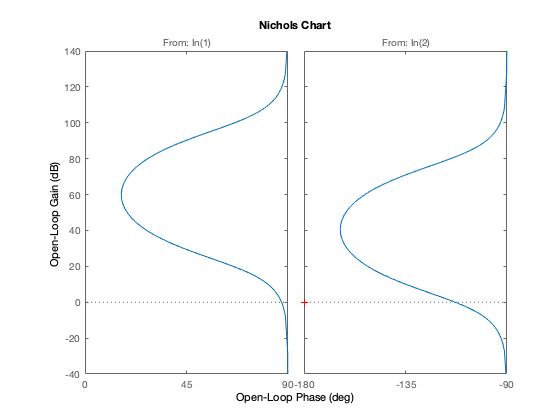

s = tf('s');
P = ss(a, [-bg b], 1, 0);
C = (kp*s+ki)/s;
L = P*C;

figure; nichols(L);

Sur la réponse fréquentielle suivante, on peut voir qu’on dispose d’une marge de gain infinie et d’une marge de phase très grande de l’ordre de 90°. Ceci explique qu’on a un dépassement faible de la consigne et que le système est stable et robuste à des perturbations extérieures comme un changement de masse du véhicule. 